# Plots Error and Output against Time

% CSV file with all colums in order of Time, Error and Output
csvFile = "/Users/saabir/Library/CloudStorage/OneDrive-TheUniversityofNottingham/General - Engineering B01-11/Code/Saabir/line_following/data/i.csv";
T = readtable(csvFile);

% Set first time to 0
T.Var1 = T.Var1 - T.Var1(1);

% Plot graph
yyaxis left
plot(T.Var1, T.Var2, '-.')
title('Error and PI Output over Time')
xlabel('Time')
ylabel('Error')

yyaxis right
plot(T.Var1, T.Var3, '-*')
ylabel('Output')

legend('Error', 'Output')


Add Grid

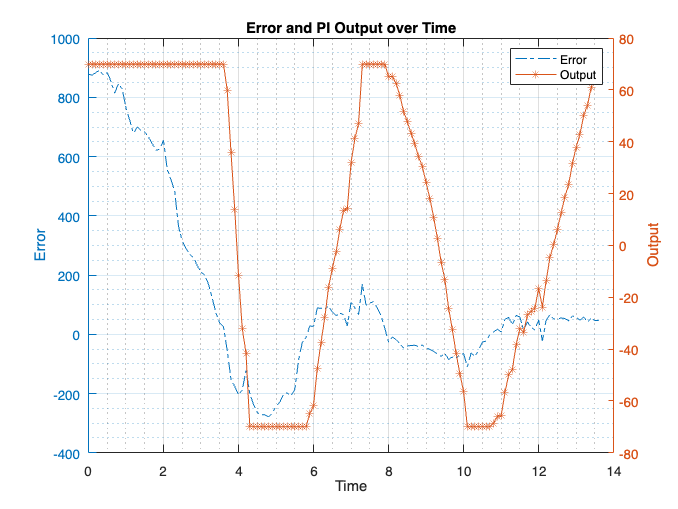

grid on
grid minor